clear all
close all
clc

calibration = pop_loadxdf('C:\Users\cybathlon\Desktop\Paradigm group\recorded_data\PA_corey2601.xdf');

Now importing...No clock offsets were available for stream "eeg"
No clock offsets were available for stream "markers"
done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


## data preprocessing

%y = pop_select(calibration, 'channel', [3,7,8,13,14,15]); % choose channels according to the recording
% y = pop_resample(y, 250);
% y = pop_rmbase(y,[],[]);
y = pop_eegfilt(calibration, 1, 0, 0, 0, 0, 0, 'fir1', 0);       % first highpass the data

eegfilt() - performing 750-point highpass filtering.
...................20....


y = pop_eegfilt(y, 0, 40, 0, 0, 0, 0, 'fir1', 0);      % then lowpass the data

eegfilt() - performing 18-point lowpass filtering.
...................20....


y = pop_reref(y,[]);

Re-referencing data


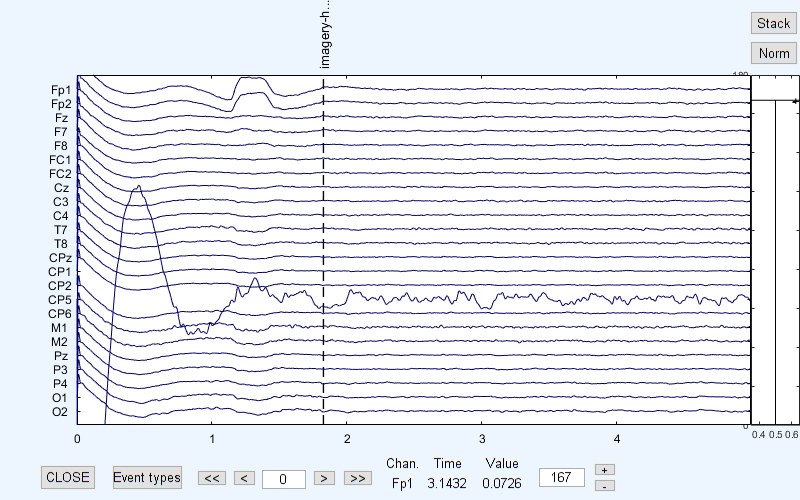

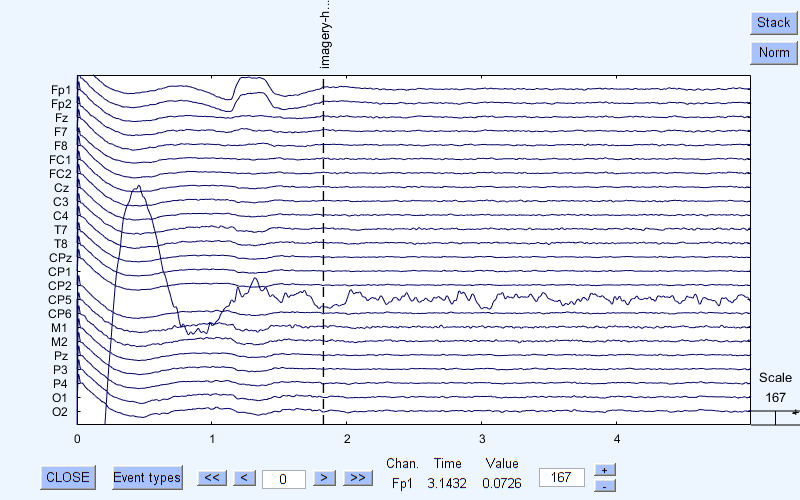

eegplot(y.data, 'eloc_file', y.chanlocs, 'srate', y.srate, 'events', y.event)

## data epoching

%EEG_epo_noError = pop_epoch(y,{'c'},[-0.5 1]); % no-error epochs
%EEG_epo_Error = pop_epoch(y,{'wl',
%'wi'},[-0.5 1]); % error epochs
EEG_hand = pop_epoch(y, {'imagery_hand'},[0 3]);

pop_epoch():210 epochs selected
Epoching...
pop_epoch():210 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_foot = pop_epoch(y, {'imagery_foot'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_subs = pop_epoch(y, {'imagery_subs'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_rotate = pop_epoch(y, {'imagery_rotate'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_auditory = pop_epoch(y, {'imagery_auditory'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_spatial = pop_epoch(y, {'imagery_spatial'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_taste = pop_epoch(y, {'imagery_taste'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG_word = pop_epoch(y, {'imagery_word'},[0 3]);

pop_epoch():30 epochs selected
Epoching...
pop_epoch():30 epochs generated
pop_epoch(): checking epochs for data discontinuity


## Get alpha and beta band power

alpha_band = pop_eegfilt(y, 8, 13, 0, 0, 0, 0, 'fir1', 0);
beta_band = pop_eegfilt(y, 13, 30, 0, 0, 0, 0, 'fir1', 0);


## Dividing the hand epochs

%EEG_hand_foot = EEG_hand.data(:,:,1:30)
EEG_hand_foot = pop_select(EEG_hand,'trial',1:30);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


EEG_hand_subs = pop_select(EEG_hand,'trial',31:60);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


EEG_hand_rotate = pop_select(EEG_hand,'trial',61:90);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


EEG_hand_auditory = pop_select(EEG_hand,'trial',91:120);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


EEG_hand_spatial = pop_select(EEG_hand,'trial',121:150);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


EEG_hand_taste = pop_select(EEG_hand,'trial',151:180);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


EEG_hand_word = pop_select(EEG_hand,'trial',181:210);

Removing 180 trial(s)...
Pop_select: removing 180 unreferenced events


## Band power of variables

alpha_band_hand_foot = pop_eegfilt(EEG_hand_foot, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_foot = pop_eegfilt(EEG_hand_foot, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_hand_subs = pop_eegfilt(EEG_hand_subs, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_subs = pop_eegfilt(EEG_hand_subs, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_hand_rotate = pop_eegfilt(EEG_hand_rotate, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_rotate= pop_eegfilt(EEG_hand_rotate, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_hand_auditory = pop_eegfilt(EEG_hand_auditory, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_auditory = pop_eegfilt(EEG_hand_auditory, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_hand_spatial = pop_eegfilt(EEG_hand_spatial, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_spatial = pop_eegfilt(EEG_hand_spatial, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_hand_taste = pop_eegfilt(EEG_hand_taste, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_taste = pop_eegfilt(EEG_hand_taste, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_hand_word = pop_eegfilt(EEG_hand_word, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_hand_word = pop_eegfilt(EEG_hand_word, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.




alpha_band_foot = pop_eegfilt(EEG_foot, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_foot = pop_eegfilt(EEG_foot, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_subs = pop_eegfilt(EEG_subs, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_subs = pop_eegfilt(EEG_subs, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_rotate = pop_eegfilt(EEG_rotate, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_rotate= pop_eegfilt(EEG_rotate, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_auditory = pop_eegfilt(EEG_auditory, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_auditory = pop_eegfilt(EEG_auditory, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_spatial = pop_eegfilt(EEG_spatial, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_spatial = pop_eegfilt(EEG_spatial, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_taste = pop_eegfilt(EEG_taste, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_taste = pop_eegfilt(EEG_taste, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



alpha_band_word = pop_eegfilt(EEG_word, 8, 13, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 93-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



beta_band_word = pop_eegfilt(EEG_word, 13, 30, 0, 0, 0, 0, 'fir1', 0);

eegfilt() - performing 57-point bandpass filtering.
            If a message, 'Matrix is close to singular or badly scaled,' appears,
            then Matlab has failed to design a good filter. As a workaround, 
            for band-pass filtering, first highpass the data, then lowpass it.



## plotting

Removing 23 channel(s)...
eeg_checkset note: data array made 3-D
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (30), corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


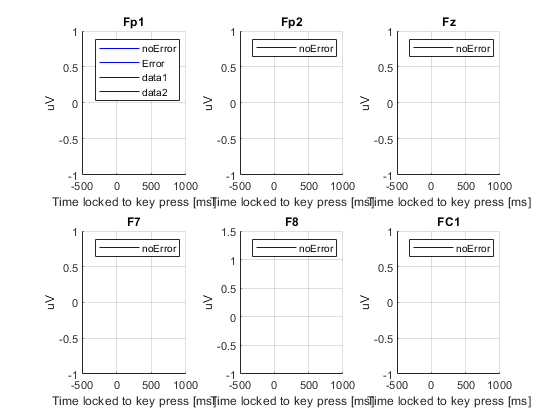

Error using plot
Vectors must be the same length.

for k=1:6
    % plotting the cz average across epochs
    chan_noError = pop_select(alpha_band_hand_foot, 'channel', k);
    %chan_Error = pop_select(alpha_band_hand_foot, 'channel', k);
    %chan_ErrorPos = pop_select(EEG_epo_Error_Pos, 'channel', k);
    %chan_ErrorInt = pop_select(EEG_epo_Error_Int, 'channel', k);
    
%     chan_noError = pop_select(chan_noError, 'notrial', 1:480);

    erp_noError = mean(squeeze(chan_noError.data),2)';
    erp_noError_std = std(squeeze(chan_noError.data),0,2)';
%     erp_noError = squeeze(chan_noError.data)';
    %erp_Error = mean(squeeze(chan_Error.data),2)';
    %erp_Error_std = std(squeeze(chan_Error.data),0,2)';
    %erp_ErrorPos = mean(squeeze(chan_ErrorPos.data),2)';
    %erp_ErrorPos_std = std(squeeze(chan_ErrorPos.data),0,2)';
    %erp_ErrorInt = mean(squeeze(chan_ErrorInt.data),2)';
    %erp_ErrorInt_std = std(squeeze(chan_ErrorInt.data),0,2)';

    t = linspace(-500,1000,size(erp_noError,2));
    
    figure(100);
    subplot(2,3,k)
    hold all
    plot(t,erp_noError,'b')
    plot(t,alpha_band_hand_foot.data,'r')
    grid on
    xlabel('Time locked to key press [ms]')
    xlim([-500 1000])
    ylabel('uV')
    %ylim([-10,10])
    legend('noError','Error')
    title(y.chanlocs(k).labels)
    
    figure(101);
    subplot(2,3,k)
    hold all
    plot(t,erp_noError,'Color',[0, 0.4470, 0.7410])
    %plot(t,erp_ErrorPos,'Color',[0.8500, 0.3250, 0.0980])
    %plot(t,erp_ErrorInt,'Color',[0.9290, 0.6940, 0.1250])
    grid on
    xlabel('Time locked to key press [ms]')
    xlim([-500 1000])
    ylabel('uV')
    ylim([-10,10])
    legend('noError','ErrorPos','ErrorInt')
    title(y.chanlocs(k).labels)
end

## Plotting Frequency bands